### 0.1 - Clear Window

clear % Clear workspace variables 
clc % Clear Command Window


## 1) SETUP

### 1.1 - Setup Variables

zero_congif = [0,0,0,0];
homeconfig = [180, -90, 90, -90];
centre = [-0.00029, 0.00037];
book_straight_collect_offset = 0.027;

L1 = 0.135;   
L2 = 0.107;  
L3 = 0.107; 
L4 = 0.109; 

% Number of interpolation steps
numSteps = 10;
numSteps_mid = 2;

% Scale for the mid-points for each book position
num_mid_points = 10;
radius_scale = 0.6;


%% BOOK TRANSLATION
% Define translation
translation = trvec2tform([-0.05, -0.01, -0.015]);

% Define 90° rotation around X-axis
rotationX = axang2tform([1 0 0 pi/2]);

% Define 90° counterclockwise rotation around Z-axis (from above)
rotationZ = axang2tform([0 0 1 pi/2]);

% Combine: First rotate X, then Z, then translate
customTransform = translation * rotationZ * rotationX; 


### 1.2 - Loading the Scenario

scenario = robotScenario(UpdateRate=1,StopTime=10);

Create a [`rigidBodyTree`](docid:robotics_ref#bvan8uq-1) object of the custom CW2 URDF.

addpath("/Users/louieburns/Library/CloudStorage/OneDrive-UniversityofLeeds/Robotics Coursework/URDFs/Robot_URDF_Visuals/urdf")  % Louie Path folder
%addpath("C:\Users\dnehu\OneDrive - University of Leeds\Robotics Coursework\URDFs\Robot_URDF\urdf")  % Dan path folder
savepath % Save filepath for next time

% Create a rigidBodyTree object of the Franka Emika Panda manipulator using loadrobot.
robotRBT = importrobot("Robot_URDF_Visuals.urdf");
robotRBT.DataFormat = "row";  % or use "column" if you prefer

Create a `rigidBodyTree`-based [`robotPlatform`](docid:robotics_ref#mw_184989ef-41a5-4055-a8a4-5460899dbc3a) object using the manipulator model.

Robot = robotPlatform("Manipulator",scenario, ...
                      RigidBodyTree=robotRBT);

Create collision objects for all 6 books. - DO NOT EDIT BOOK POSITIONS IN THIS SECTION

book_1 = robotPlatform("Book_1",scenario,Collision="mesh", InitialBaseOrientation=[0.706923132	0.706925728	0.016057751	0.016057692], InitialBasePosition=[0.014018	-0.30839	0.10381]);
updateMesh(book_1,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0 0])

book_2 = robotPlatform("Book_2",scenario,Collision="mesh", InitialBaseOrientation=[0.706747289	0.706749885	0.022504157	0.022504074], InitialBasePosition=[-0.019668	0.30852	-0.032738]);
updateMesh(book_2,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0.682 0])
 
book_3 = robotPlatform("Book_3",scenario,Collision="mesh", InitialBaseOrientation=[0.40083391	0.400835382	-0.582522818	-0.582520678], InitialBasePosition=[0.28417	-0.10873	-0.082996]);
updateMesh(book_3,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 1 0])

book_4 = robotPlatform("Book_4",scenario,Collision="mesh", InitialBaseOrientation=[0.206562054	0.206562812	0.676264476	0.676261992], InitialBasePosition=[-0.16721	-0.24817	0.32703]);
updateMesh(book_4,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[0 1 0])

book_5 = robotPlatform("Book_5",scenario,Collision="mesh", InitialBaseOrientation=[0.636410903	0.636413241	0.308188293	0.308187161], InitialBasePosition=[-0.24541	0.19397	0.10258]);
updateMesh(book_5,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[0 1 1])

book_6 = robotPlatform("Book_6",scenario,Collision="mesh", InitialBaseOrientation=[0.276366618	0.276367633	0.650863095	0.650860704], InitialBasePosition=[-0.22945	-0.22148	0.10258]);
updateMesh(book_6,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0 1])


## 2) Setup Robot

### 2.1 - Adding Robot Collisions 

showdetails(robotRBT)

--------------------
Robot: (6 bodies)

 Idx             Body Name      Joint Name      Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------      ----------      ----------             ----------------   ----------------
   1                Link_1          Joint1        revolute                 Base_Link(0)   Link_2(2)  
   2                Link_2          Joint2        revolute                    Link_1(1)   Link_3(3)  
   3                Link_3          Joint3        revolute                    Link_2(2)   Link_4(4)  
   4                Link_4          Joint4        revolute                    Link_3(3)   End_Effector_1(5)  End_Effector_2(6)  
   5        End_Effector_1        Joint5_1       prismatic                    Link_4(4)   
   6        End_Effector_2        Joint5_2       prismatic                    Link_4(4)   
--------------------


home = homeConfiguration(robotRBT);

% ax = show(robotRBT, "Frames","off", "Collisions","off"); % Check robot loaded correctly

% Add collison to the end effector of your robot
addCollision(robotRBT.Bodies{end},"sphere",[0.005], trvec2tform([0,0,0])) % add new collision
addVisual(robotRBT.Bodies{end},"sphere",[0.005], trvec2tform([0,0,0]))

isColliding = checkCollision(robotRBT, homeConfiguration(robotRBT), IgnoreSelfCollision="on");

% Possibly useful functions: 
clearCollision(robotRBT.Bodies{1,4})


### 2.1 - Visualising The Scene

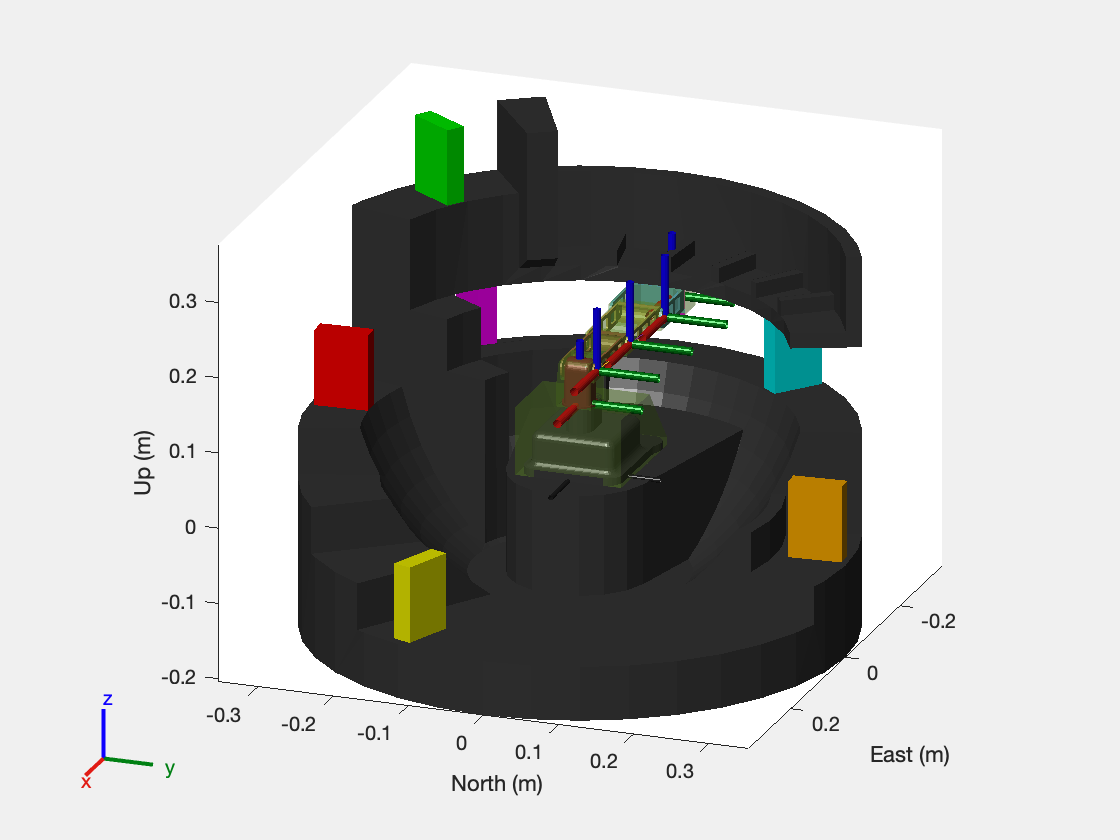

% Show scene once at the start
hold off
[ax, plotFrames] = show3D(scenario, Collisions="on");
[az, el] = view(ax);
view (ax, 110, 20)
axis equal
light
drawnow
hold on

## 3) Inverse Kinematics

Starting in the home configuration, solve for the arm reaching the point where the Book_1 frame lies.

### 3.1 Calculate the book co-ordinates

% Define the books data (initial base positions and updated colors)
book_1 = struct('name', 'Book_1', 'position', [0.014018 -0.30839 0.13881], 'bookSize', [0.025 0.1 0.07], 'Color', [1 0 0]);   % Red
book_2 = struct('name', 'Book_2', 'position', [-0.019668 0.30852 -0.002738], 'bookSize', [0.025 0.1 0.07], 'Color', [1 0 1]);   % Pink
book_3 = struct('name', 'Book_3', 'position', [0.28417 -0.10873 -0.047996], 'bookSize', [0.025 0.1 0.07], 'Color', [0 1 0]);   % Green
book_4 = struct('name', 'Book_4', 'position', [-0.16721 -0.24817 0.36203], 'bookSize', [0.025 0.1 0.07], 'Color', [1 0.647 0]); % Orange
book_5 = struct('name', 'Book_5', 'position', [-0.24541 0.19397 0.13758], 'bookSize', [0.025 0.1 0.07], 'Color', [1 1 0]);   % Yellow
book_6 = struct('name', 'Book_6', 'position', [-0.22945 -0.22148 0.13758], 'bookSize', [0.025 0.1 0.07], 'Color', [0 0 1]);    % Blue

% Put the books in a cell array
books = {book_1, book_6, book_4, book_2, book_3, book_5};


coordinates = zeros(length(books), 3); % Initialize a matrix to store the coordinates

for i = 1:length(books)
    coordinates(i, :) = books{i}.position; % Get the position of each book and store it in the matrix
end

% Display the coordinates matrix
disp(coordinates);

    0.0140   -0.3084    0.1388
   -0.2294   -0.2215    0.1376
   -0.1672   -0.2482    0.3620
   -0.0197    0.3085   -0.0027
    0.2842   -0.1087   -0.0480
   -0.2454    0.1940    0.1376



bookPositions = coordinates;


### Calculate Book Final Cords

shelf_coords = [ -0.247203, -0.0888485, 0.17703;   % Red (bottom)
                 -0.125306,  0.229985, 0.17703;    % Purple (bottom)
                 -0.230686,  0.122,    0.17703;    % Green (bottom)
                 -0.26,     -0.015964705, 0.17703;   % Orange (bottom)
                 -0.256188,  0.0580598,  0.17703;    % Yellow (bottom)
                 -0.184746,  0.186741,   0.17703];   % Blue (bottom)

## 4) Trajectory Generation

### 4.1 Calculate Mid Positions for each of the points for ALL BOOKS

%This calculates the radius away from the centre the point is and the height
results = calculateResults(bookPositions, L1);

Results Matrix (Radius, Original Z):
    0.3087    0.0038
    0.3189    0.0026
    0.2992    0.2270
    0.3091   -0.1377
    0.3043   -0.1830
    0.3128    0.0026




results_shelf = calculateResults(shelf_coords, L1)

Results Matrix (Radius, Original Z):
    0.2627    0.0420
    0.2619    0.0420
    0.2610    0.0420
    0.2605    0.0420
    0.2627    0.0420
    0.2627    0.0420



results_shelf =     0.2627    0.0420
    0.2619    0.0420
    0.2610    0.0420
    0.2605    0.0420
    0.2627    0.0420
    0.2627    0.0420



%% Fix a slight height issue for books with straight end collection method with an offset
results(1, 2) = results(1, 2) - book_straight_collect_offset;
results(2, 2) = results(2, 2) - book_straight_collect_offset;
results(6, 2) = results(6, 2) - book_straight_collect_offset;



%Loop through and make a matrix full of each books individual points

for i = 1:6
    eval(['results_book_' num2str(i) ' = results(' num2str(i) ', :);']);
end

%Create 10 points within each matrix which are at smaller radius values

for i = 1:6
    % Define the book name dynamically
    results_book_name = ['results_book_' num2str(i)];
    results_book_10_points = zeros(num_mid_points, 2);  % Initialize the result array for each book
    
    % Loop through the mid-points and calculate for each book
    for j = 1:num_mid_points
        difference = (eval([results_book_name '(1, 1)']) - (radius_scale * eval([results_book_name '(1, 1)']))) / num_mid_points; 
        results_book_10_points(j, 1) = eval([results_book_name '(1, 1)']) - ((1 + num_mid_points - j) * difference);
        results_book_10_points(j, 2) = eval([results_book_name '(1, 2)']);
    end
    
    % Assign the calculated points to a dynamically named variable
    assignin('base', [results_book_name '_10_points'], results_book_10_points);
end


###   4.2 - Find Theta 1

% Loop to create matrices with different sizes for book numbers
for i = 1:6
    if i == 3 || i == 4 || i == 5
        % For book numbers 3, 4, and 5, create a 1x4 matrix
        eval(['final_angles_' num2str(i) ' = zeros(1, 4);']);
    else
        % For book numbers 1, 2, and 6, create a 10x4 matrix
        eval(['final_angles_' num2str(i) ' = zeros(10, 4);']);
    end
end

%    Create Matrix for shelf angles

shelf_angles = zeros(6, 4);

%     4.2.1 Find Theta 1 for book cords
final_angles_1(:, 1) = calculateTheta1(bookPositions(1, :), centre)

final_angles_1 =   -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0
  -92.6532         0         0         0


final_angles_2(:, 1) = calculateTheta1(bookPositions(2, :), centre)

final_angles_2 =   -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0
  -44.0714         0         0         0


final_angles_3(:, 1) = calculateTheta1(bookPositions(3, :), centre)

final_angles_3 =   -56.1146         0         0         0


final_angles_4(:, 1) = calculateTheta1(bookPositions(4, :), centre)

final_angles_4 =    86.4017         0         0         0


final_angles_5(:, 1) = calculateTheta1(bookPositions(5, :), centre)

final_angles_5 =  -159.0165         0         0         0


final_angles_6(:, 1) = calculateTheta1(bookPositions(6, :), centre)

final_angles_6 =    38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0
   38.3023         0         0         0



%     4.2.1 Find Theta 1 for shelf cords
shelf_angles(:, 1) = calculateTheta1(results_shelf(1, :), centre);

###  4.3 - Find Theta 2 & 3 & 4

%     4.2.2 Find Theta 2 & 3 & 4
%     For the values that are for books 3,4,5 only do the actual book position
%     Also calculate for books 3,4,5 a different function so end effector can bend

final_angles_1(:, 2:4) = calculateTheta234(results_book_1_10_points, L2, L3, L4);
final_angles_2(:, 2:4) = calculateTheta234(results_book_2_10_points, L2, L3, L4);
final_angles_3(:, 2:4) = calculateTheta234_bend(results_book_3, L2, L3, L4);
final_angles_4(:, 2:4) = calculateTheta234_bend(results_book_4, L2, L3, L4);
final_angles_5(:, 2:4) = calculateTheta234_bend(results_book_5, L2, L3, L4);
final_angles_6(:, 2:4) = calculateTheta234(results_book_6_10_points, L2, L3, L4);


% Find Shelf Angles
shelf_angles(:, 2:4) = calculateTheta234_bend(results_shelf, L2, L3, L4);

###  4.4 - Add An Extra Position For Book 2 To Avoid Wall

% Extract the first row from final_angles_2
first_row = final_angles_2(1, :);

% Modify the first column of the first row to be negative
first_row(1) = -first_row(1);

% Insert the new row at the top of final_angles_2
final_angles_2 = [first_row; final_angles_2];  % Prepend the modified row


### 5) Move The Robot

up_value =   -56.1146  -90.0000         0         0


up_value =    86.4017  -90.0000         0         0


up_value =  -159.0165  -90.0000         0         0


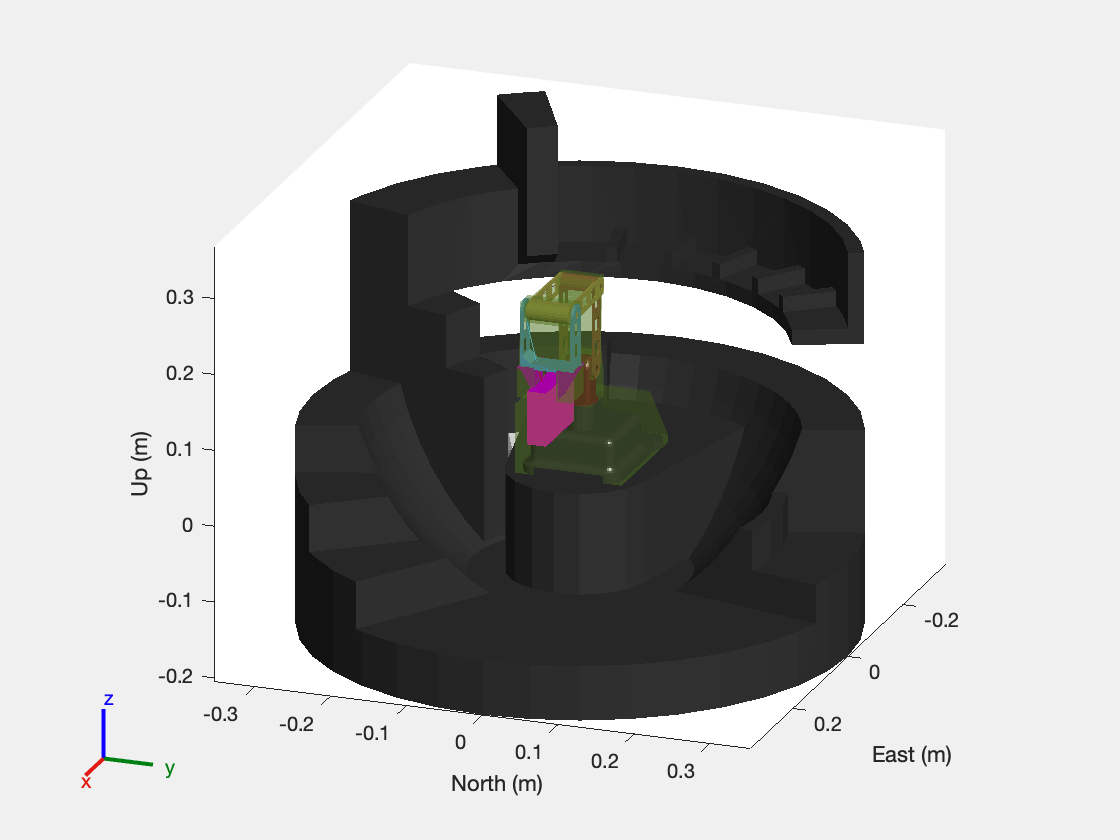

% Define the number of points in final_angles_1

% Loop through all final angles configurations (final_angles_1 to final_angles_6)
for k = 1:6

    numPoints = size(eval(['final_angles_' num2str(k)]), 1);  % Number of points (rows)

    % Dynamically select final_angles for each configuration
    current_angles = eval(['final_angles_' num2str(k)]);  % final_angles_1, final_angles_2, ..., final_angles_6
    
    % Check if the current book is 1, 2, or 6
    if k == 1 || k == 2 || k == 6
        % Animate the robot trajectory from home configuration to the first point
        animateRobotTrajectory(scenario, Robot, ax, homeconfig, current_angles(1, :), numSteps);
        
                    % Slow Movement to the Extra Position for Book 2 ONLY
            if k == 2
                animateRobotTrajectory(scenario, Robot, ax, current_angles(1, :), current_angles(2, :), numSteps);
            else

            end

        % Loop through all consecutive points for the current final angles
        for i = (k == 2) + 1 : numPoints-1

            % Extract the current point and the next point
            firstPoint = current_angles(i, :);
            secondPoint = current_angles(i+1, :);
            
            % Call the animateRobotTrajectory function for each pair of consecutive points
            animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, numSteps_mid);
        end

        % Dynamically select the current book using books{k}
        currentBook = books{k};  % Access books{1}, books{2}, ..., books{6}
        
        % Now access the fields of the structure using dot notation
        attach(Robot, currentBook.name, "End_Effector_1", ...
            'ChildToParentTransform', customTransform);

        % Loop through all consecutive points in reverse order for the current angles
        for i = numPoints:-1:2
            % Extract the current point and the previous point
            firstPoint = current_angles(i, :);
            secondPoint = current_angles(i-1, :);

            %% This extra steps makes sure the robot moves slowly to last position if it's book 2
            
            if k == 2 && i == 2
                t = numSteps;
            else
                t = numSteps_mid;
            end
            
            % Call the animateRobotTrajectory function for each pair of consecutive points
            animateRobotTrajectory(scenario, Robot, ax, firstPoint, secondPoint, t);
        end

        % Animate the robot trajectory from the first point back to home configuration
        animateRobotTrajectory(scenario, Robot, ax, current_angles(1, :), homeconfig, numSteps);
        
        % Detach the robot at the end of the current loop iteration
        detach(Robot);


    else
        % Up Config for book 3,4,5
        up_value = [current_angles(1, 1), -90, 0, 0]
        animateRobotTrajectory(scenario, Robot, ax, homeconfig, up_value, numSteps);
        animateRobotTrajectory(scenario, Robot, ax, up_value, current_angles, numSteps);

        % Dynamically select the current book using books{k}
        currentBook = books{k};  % Access books{1}, books{2}, ..., books{6}
        
        % Now access the fields of the structure using dot notation
        attach(Robot, currentBook.name, "End_Effector_1", ...
            'ChildToParentTransform', customTransform);

        animateRobotTrajectory(scenario, Robot, ax, current_angles, up_value, numSteps);
        animateRobotTrajectory(scenario, Robot, ax, up_value, homeconfig, numSteps);

                % Detach the robot at the end of the current loop iteration
        detach(Robot);

    end
end

## A) FUNCTIONS TO CALL

### A.1 - RADIUS AND HEIGHT FUNCTION

function results = calculateResults(bookPositions, L1)
    % Get the number of rows
    numRows = size(bookPositions, 1);

    % Pre-allocate the results matrix for efficiency
    % It will have the same number of rows as bookPositions, but only 2 columns
    results = zeros(numRows, 2);

    % Loop through each row of the bookPositions matrix
    for i = 1:numRows
        % Extract the first element (a) and second element (b) from the current row
        a = bookPositions(i, 1);
        b = bookPositions(i, 2);

        % Calculate the radius r = sqrt(a^2 + b^2)
        radius = sqrt(a^2 + b^2);
        % Alternatively, you can use hypot(a, b), which is numerically more robust
        % radius = hypot(a, b);

        % Assign the calculated radius to the first column of the results matrix
        results(i, 1) = radius;

        % Assign the third element from the original row to the second column
        results(i, 2) = bookPositions(i, 3);

        results(i, 2) = results(i, 2) - L1;
    end

    % Display the final results matrix
    disp('Results Matrix (Radius, Original Z):');
    disp(results);
end

### A.2 - ANIMATE ROBOT FUNCTION

function animateRobotTrajectory(scenario, Robot, ax, q_start_deg, q_end_deg, numSteps, hideFrames)
    if nargin < 7
        hideFrames = true;
    end

    % Ensure input vectors are row vectors
    q_start_deg = reshape(q_start_deg, 1, []);
    q_end_deg = reshape(q_end_deg, 1, []);

    % Pad to 6 joints if needed (e.g. robot expects 6 DOF input)
    if length(q_start_deg) < 6
        q_start_deg = [q_start_deg, zeros(1, 6 - length(q_start_deg))];
    end
    if length(q_end_deg) < 6
        q_end_deg = [q_end_deg, zeros(1, 6 - length(q_end_deg))];
    end

    % Convert degrees to radians
    q_start = deg2rad(q_start_deg);
    q_end = deg2rad(q_end_deg);

    % Wrap angle differences to ensure shortest path
    delta = wrapToPi(q_end - q_start);  % ensures minimal rotation

    % Time parameter [0, 1]
    t = linspace(0, 1, numSteps);
    s = 0.5 * (1 - cos(pi * t));  % Cosine ease-in-out

    % Interpolate trajectory
    q_traj = q_start + s' .* delta;

    % ---- Animate ----
    for k = 1:numSteps
        move(Robot, "joint", q_traj(k, :));

        cla(ax);
        show3D(scenario, Collisions="on");
        light(ax, 'Position', [1 1 1], 'Style', 'infinite');
        view(ax, 110, 20);

        if hideFrames
            gfx_Frames = findall(ax, 'FaceColor', 'flat');
            set(gfx_Frames, 'FaceAlpha', 0);
            gfx_Base_Frame = findall(ax, 'DisplayName', 'Base_Link');
            set(gfx_Base_Frame, 'FaceAlpha', 0);
        end

        drawnow;
        pause(0.02);
    end
end


### A.3 - FIND THETA 1 FUNCTION

function theta1_values = calculateTheta1(bookPositions, centre)
    numRows = size(bookPositions, 1);
    theta1_values = zeros(numRows, 1);

    for i = 1:numRows
        P = bookPositions(i, :);
        P(1) = -(P(1) - centre(1));
        P(2) = P(2) - centre(2);
        theta1 = atan2(P(2), P(1));
        theta1_values(i) = rad2deg(theta1);
    end
end


### A.4.1 - FIND THETA 2 FUNCTION ALL BOOKS

function theta_values = calculateTheta234(results, L2, L3, L4)
    numRows = size(results, 1);
    theta_values = zeros(numRows, 3);

    for i = 1:numRows
        r_target = results(i, 1);
        z_target = results(i, 2);
        z_target = -z_target;  % Flip the z-coordinate based on the setup

        % Calculate the angle to the target in the plane (XY)
        angle_to_target = atan2(z_target, r_target);

        % Calculate the wrist position
        wrist_r = r_target - L4 * cos(angle_to_target);
        wrist_z = z_target - L4 * sin(angle_to_target);

        % Calculate the distance from the wrist to the base
        d = sqrt(wrist_r^2 + wrist_z^2);

        % Solve for theta3 using the law of cosines
        cos_theta3 = (d^2 - L2^2 - L3^2) / (2 * L2 * L3);
        cos_theta3 = min(max(cos_theta3, -1), 1);
        theta3 = acos(cos_theta3);

        % Solve for theta2
        alpha = atan2(wrist_z, wrist_r);
        cos_beta = (L2^2 + d^2 - L3^2) / (2 * L2 * d);
        cos_beta = min(max(cos_beta, -1), 1);
        beta = acos(cos_beta);
        theta2 = alpha - beta;

        % Calculate theta4 based on previous angles to keep the last limb horizontal
        % Theta4 is adjusted relative to theta2 and theta3 to ensure it remains horizontal with the ground

        % Calculate the orientation of the third limb (theta2 + theta3 combined)
        orientation_of_third_limb = theta2 + theta3;
        
        % Ensure the last joint (theta4) makes the final limb horizontal relative to the ground
        theta4 = orientation_of_third_limb;  % Adjust to make the final joint horizontal

        % Store the calculated angles in the output array, converting to degrees
        theta_values(i, 1) = rad2deg(theta2);  % Theta 2
        theta_values(i, 2) = rad2deg(theta3);  % Theta 3
        theta_values(i, 3) = rad2deg(theta4);  % Theta 4
    end
end


### A.4.2 - FIND THETA 2 FUNCTION BOOKS 3,4,5

% Function to calculate Theta 2, 3, and 4
function theta_values = calculateTheta234_bend(results, L2, L3, L4)
    numRows = size(results, 1);
    theta_values = zeros(numRows, 3);

    for i = 1:numRows
        r_target = results(i, 1);
        z_target = results(i, 2);
        z_target = -z_target;

        angle_to_target = atan2(z_target, r_target);

        wrist_r = r_target - L4 * cos(angle_to_target);
        wrist_z = z_target - L4 * sin(angle_to_target);

        d = sqrt(wrist_r^2 + wrist_z^2);

        cos_theta3 = (d^2 - L2^2 - L3^2) / (2 * L2 * L3);
        cos_theta3 = min(max(cos_theta3, -1), 1);
        theta3 = acos(cos_theta3);

        alpha = atan2(wrist_z, wrist_r);
        cos_beta = (L2^2 + d^2 - L3^2) / (2 * L2 * d);
        cos_beta = min(max(cos_beta, -1), 1);
        beta = acos(cos_beta);
        theta2 = alpha - beta;

        theta4 = angle_to_target - theta2 - theta3;

        theta_values(i, 1) = rad2deg(theta2);
        theta_values(i, 2) = rad2deg(theta3);
        theta_values(i, 3) = rad2deg(theta4);
    end
end